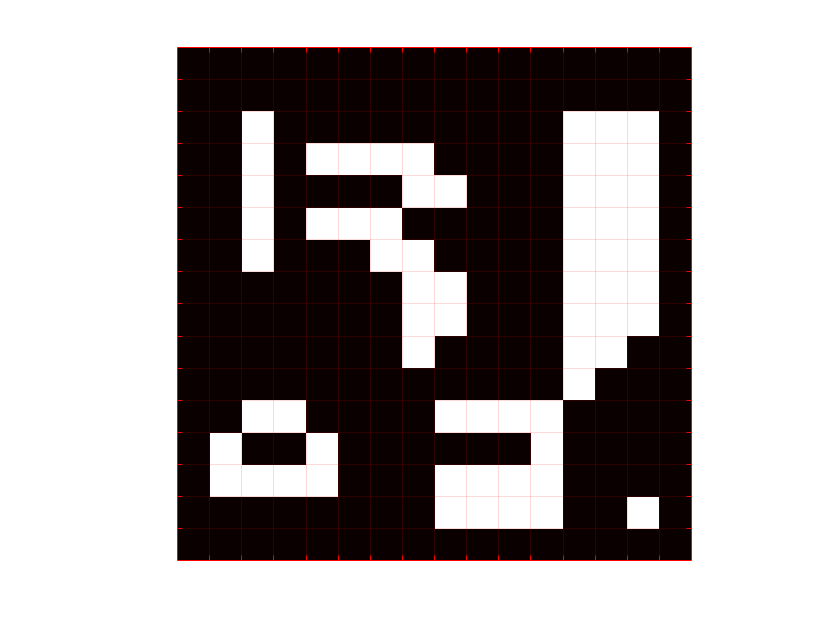

% doc bwlabel
clear all;close all;
load Image1.mat
imagesc(Image1);
imagegrid(gca,size(Image1));
colormap(gca, hot);

% e1 

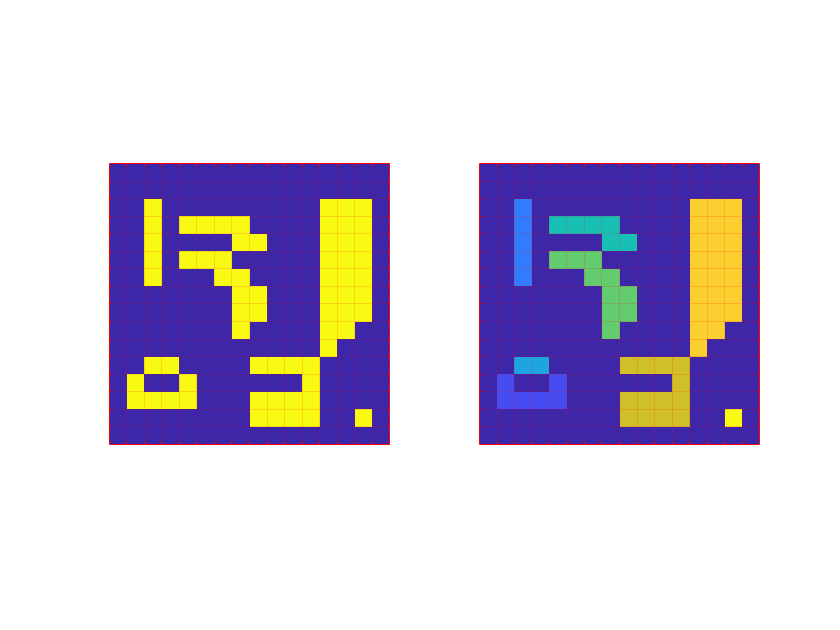

L4 = bwlabel(Image1,4);
figure;
subplot(1,2,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
%colormap(gca, "hot");
subplot(1,2,2);
imagesc(L4);
imagegrid(gca,size(L4));

%colormap(gca,'hot');

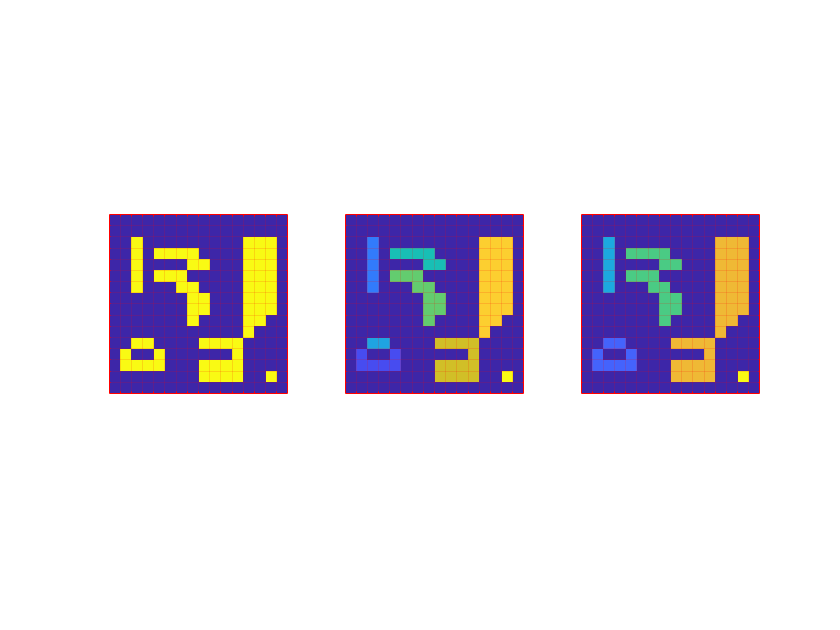

% e2
L8 = bwlabel(Image1,8);
figure;
subplot(1,3,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
%colormap(gca, "hot");
subplot(1,3,2);
imagesc(L4);
imagegrid(gca,size(L4));
%colormap(gca,'hot');
subplot(1,3,3);
imagesc(L8);
imagegrid(gca,size(L8));

%colormap(gca,'hot');
%RGB4 = label2rgb(L4, 'spring', 'c', 'shuffle');
%imagesc(RGB4);
%imagegrid(gca,size(RGB4));

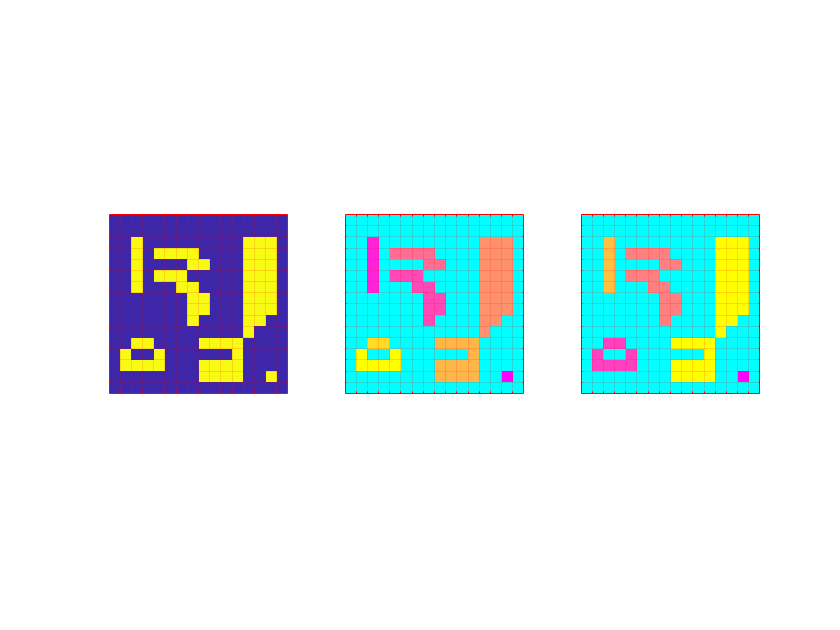

% e3
figure;
subplot(1,3,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
%colormap(gca, "hot");
subplot(1,3,2);
RGB4 = label2rgb(L4, 'spring', 'c', 'shuffle');
imagesc(RGB4);
imagegrid(gca,size(RGB4));
%colormap(gca,'hot');
subplot(1,3,3);
RGB8 = label2rgb(L8, 'spring', 'c', 'shuffle');
imagesc(RGB8);
imagegrid(gca,size(RGB8));

% e4
stats8 = regionprops(L8, 'Area');
val = stats8(1).Area;

% e5
val1 = stats8(1).Area;
val2 = stats8(2).Area;
val3 = stats8(3).Area;

% e6
allArea = [stats8.Area];

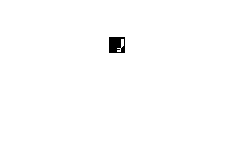

% e7
idx = find([stats8.Area] > 16);
BW2 = ismember(L8,idx);
figure;
imshow(BW2);

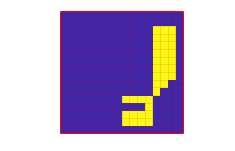

imagesc(BW2);
imagegrid(gca,size(BW2));

% e8
peri8 = regionprops(L8, 'Perimeter');
allPerimeter = [peri8.Perimeter];

% e9
idx = find(allPerimeter>20);
number = size(idx,2);

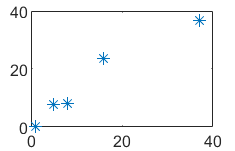

% e10
plot(allArea, allPerimeter, '*');

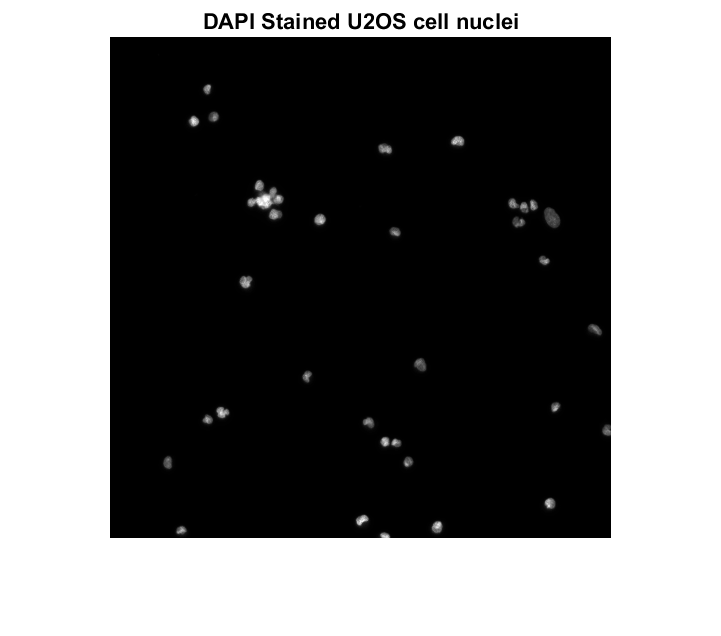

% e11
clear all;close all;clc; % Clean the workspace
I16 = imread('CellData\Sample E2 - U2OS DAPI channel.tiff');
I16c = imcrop(I16, [700 900 500 500]); % Crop region from raw image
Im = im2uint8(I16c); % Convert region into 8-bit grayscale
imshow(Im, [0 150]); title('DAPI Stained U2OS cell nuclei');

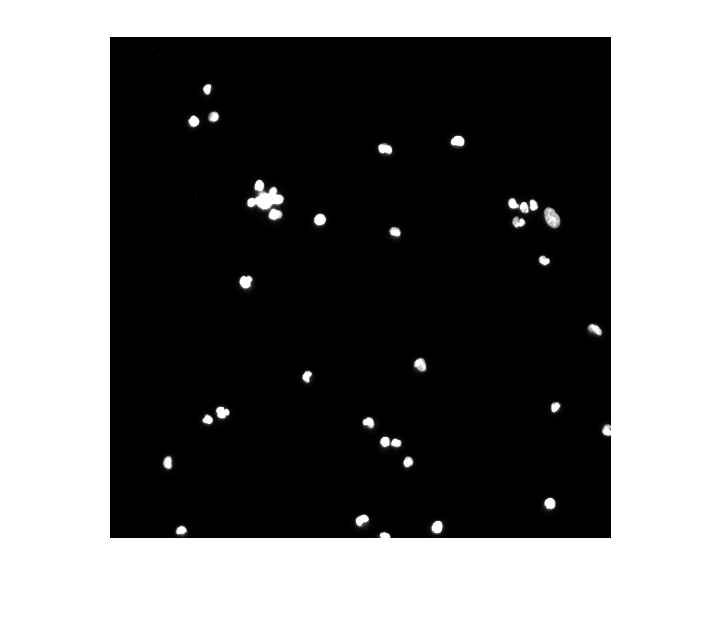

% e12
imshow(Im, [0 50]);

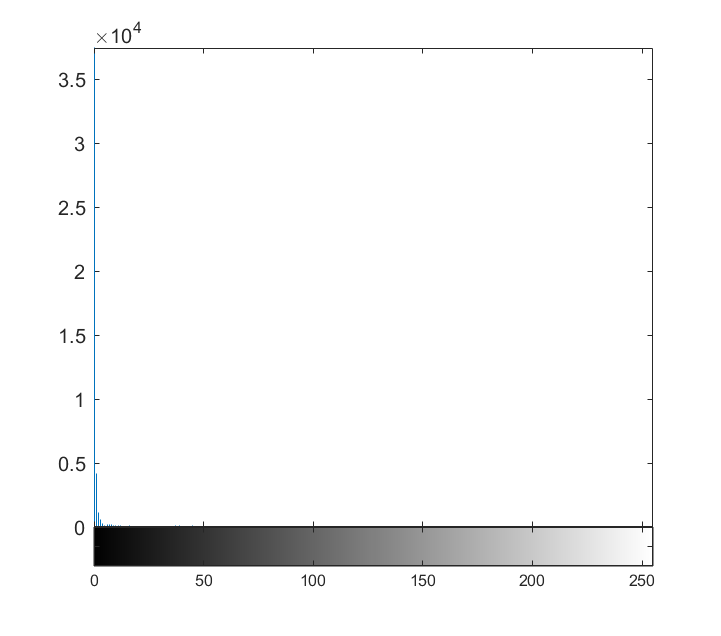

% e13
imhist(Im);

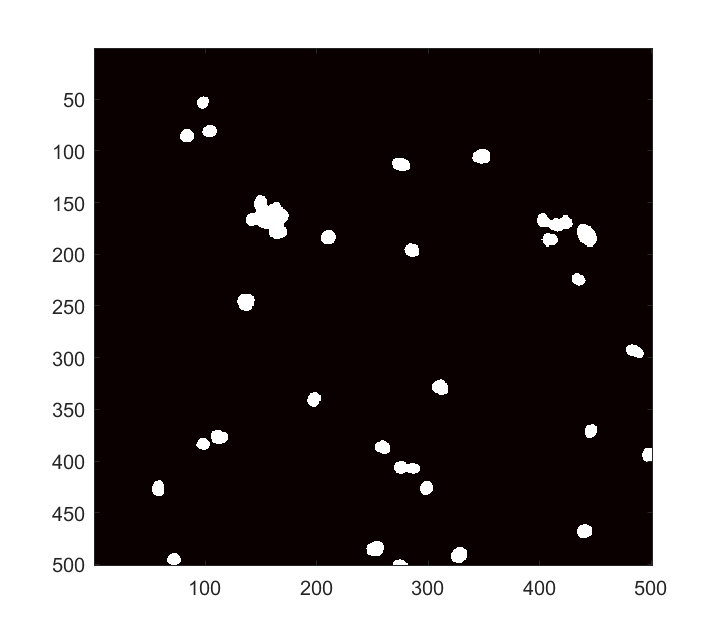

Im1 = Im;
thre = 4;
Im1(Im>thre) = 1;
Im1(Im<=thre) = 0;
imagesc(Im1);
colormap(gca,'hot');

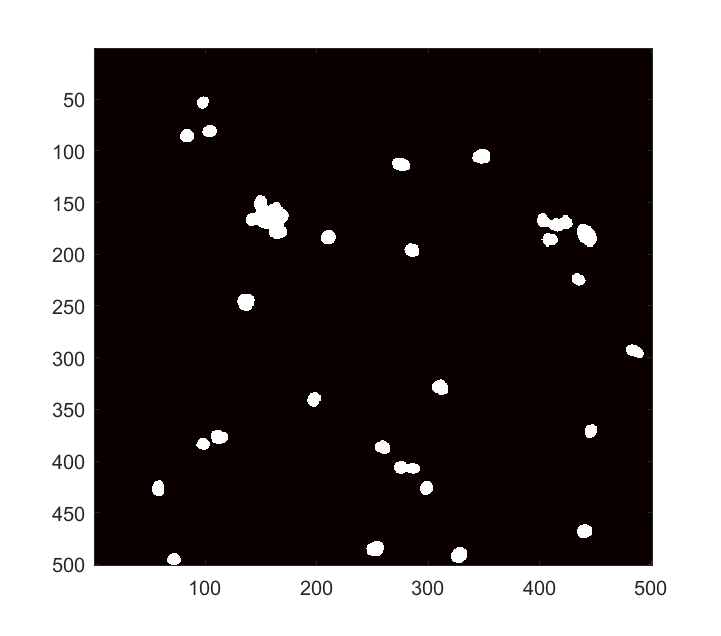

% e14
J = imclearborder(Im1,4);
imagesc(J);
colormap(gca,'hot');

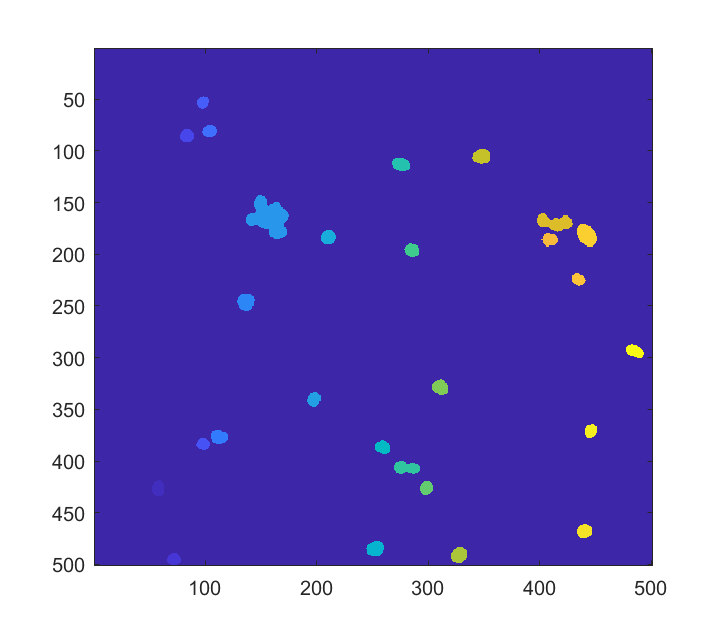

% e15
% se = strel('disk',5);
% Im2 = mopen(J,se);
% figure;
% imagesc(Im2);
% colormap(gca,'hot');
Im3 = bwlabel(J,8);
imagesc(Im3);

%colormap(gca,'hot');


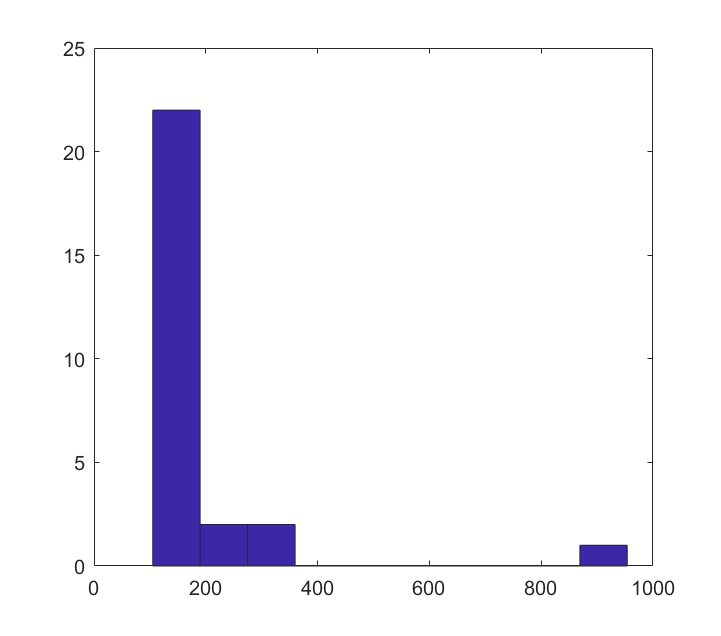

% e16
area_1 = regionprops(Im3,'Area');
area_2 = [area_1.Area];
hist(area_2);

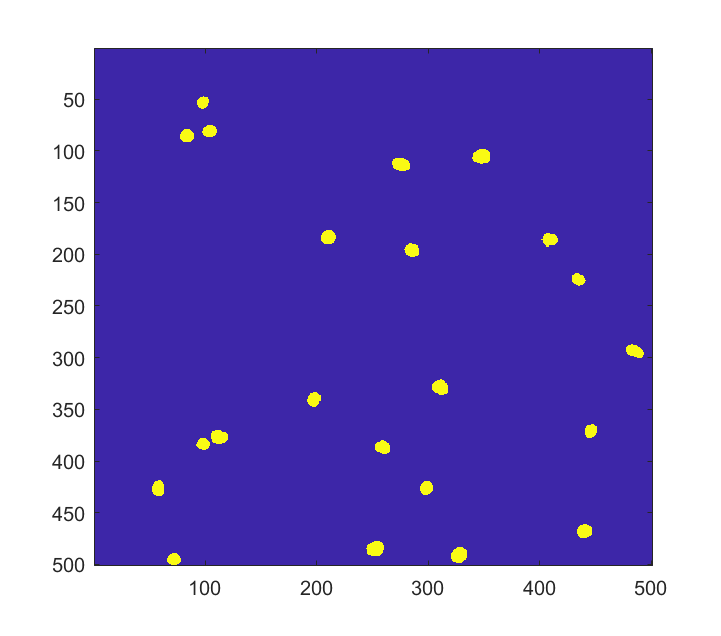

% e17
%min_area = 0;
max_area = 190;
idx = find(area_2 <= max_area);
number = size(idx,2);
BW = ismember(Im3,idx);
imagesc(BW);

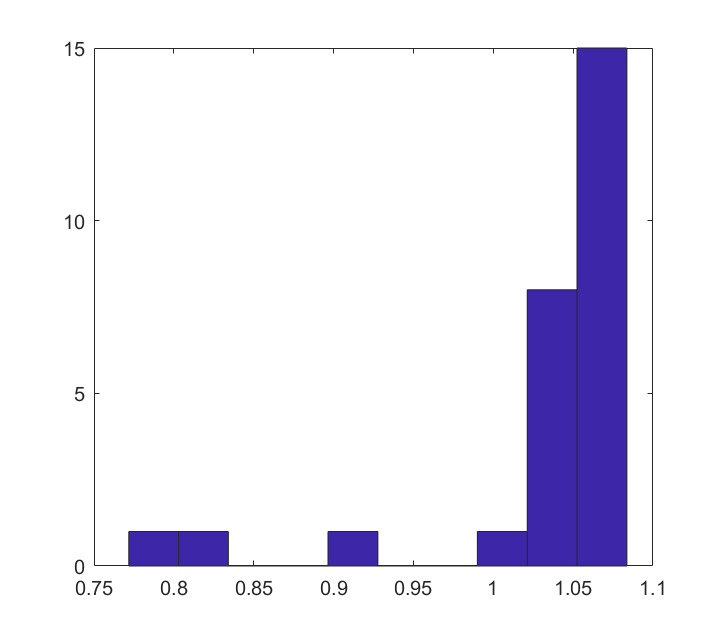

% e18
per_1 = regionprops(Im3,'Perimeter');
per_2 = [per_1.Perimeter];
r = 2.*sqrt(pi.*area_2)./per_2;
hist(r);

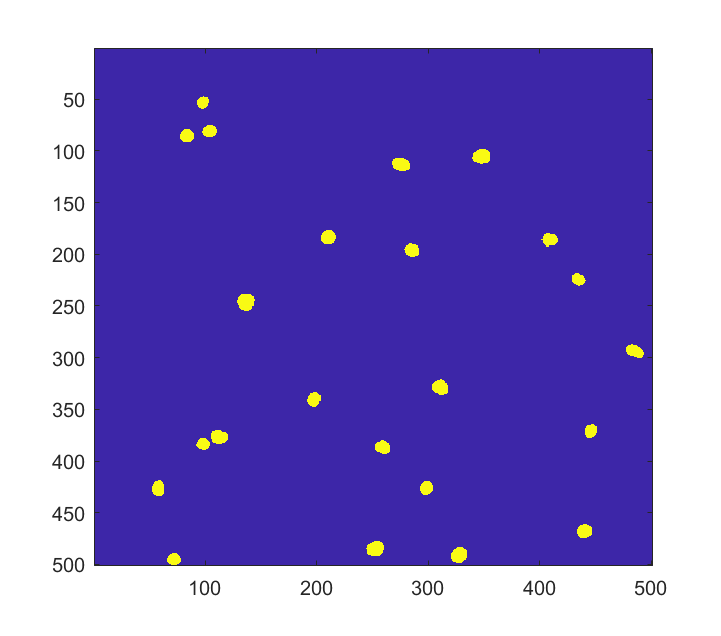

min_r = 1.02;
idx = find(r >= min_r);
number = size(idx,2);
rr = ismember(Im3,idx);
imagesc(rr);

% e19
cells = rr&BW;
imagesc(cells);

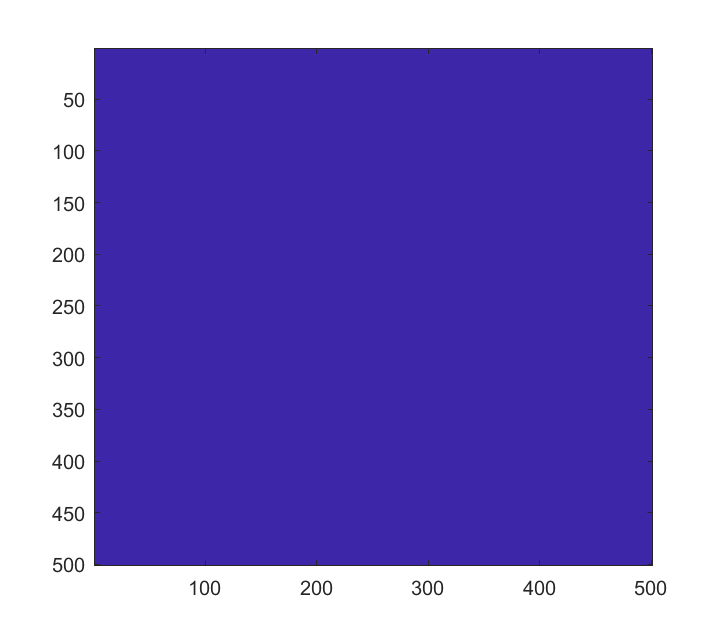

% e20
[I,N] = CountCellNuclei(Im1);

%imagesc(I);

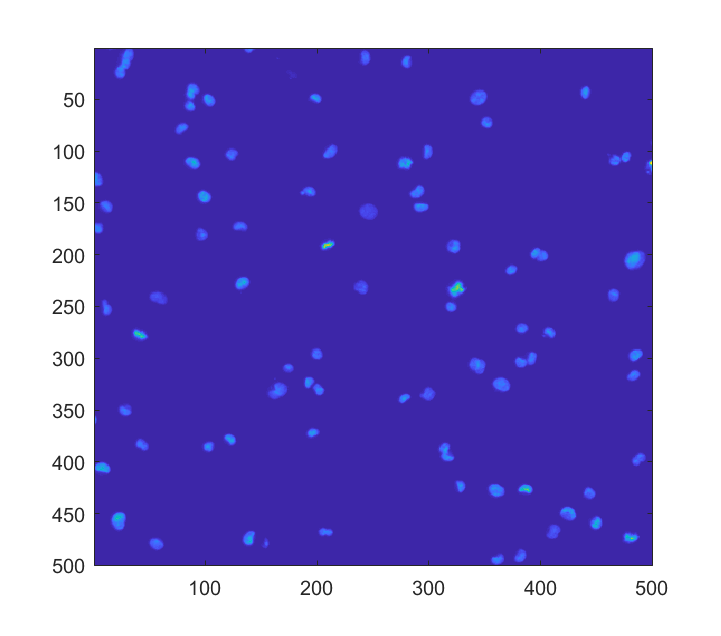

% e21 22 23
I1 = imread('CellData\Sample E2 - U2OS DAPI channel.tiff');
I2 = imread('CellData\Sample G1 - COS7 cells DAPI channel.tiff');
I1_1 = imcrop(I1,[700,900,500,500]);
I1_2 = imcrop(I1,[0,0,500,500]);
I1_3 = imcrop(I1,[600,200,500,500]);
I1_4 = imcrop(I1,[1300,0,500,500]);
I1_5 = imcrop(I2,[900,500,500,500]);
I2_1 = imcrop(I2,[0,0,500,500]);
I2_2 = imcrop(I2,[500,0,500,500]);
I2_3 = imcrop(I2,[0,500,500,500]);
I2_4 = imcrop(I2,[500,500,500,500]);
I2_5 = imcrop(I2,[1000,0,500,500]);
I2_6 = imcrop(I2,[1000,500,500,500]);
I1_1 = im2uint8(I1_1);
I1_2 = im2uint8(I1_2);
I1_3 = im2uint8(I1_3);
I1_4 = im2uint8(I1_4);
I1_5 = im2uint8(I1_5);
I2_1 = im2uint8(I2_1);
I2_2 = im2uint8(I2_2);
I2_3 = im2uint8(I2_3);
I2_4 = im2uint8(I2_4);
I2_5 = im2uint8(I2_5);
I2_6 = im2uint8(I2_6);
imagesc(I2_1)

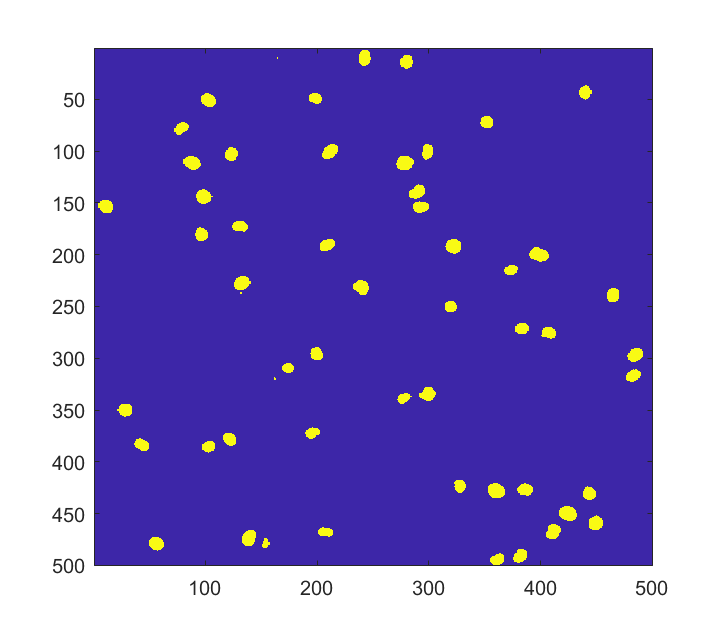

[I,N] = CountCellNuclei(I2_1);

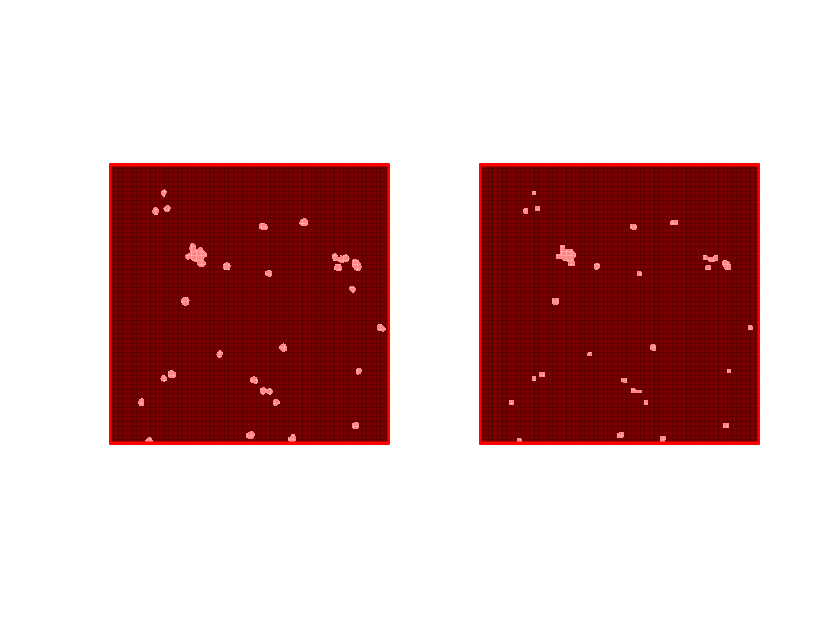

% e24
se = strel('disk',1);
J1 = imerode(J,se);
se = strel('square',7);
J1 = imopen(J1,se);
se = strel('square',5);
J1 = imclose(J1,se);
figure;
subplot(1,2,1);
imagesc(J);
imagegrid(gca,2*size(J));
colormap(gca,'gray');
subplot(1,2,2);
imagesc(J1);
imagegrid(gca,2*size(J));
colormap(gca,'gray');